% 1. Performing Convolution
x = [3,11,7,0,-1,4,2];
h = [2, 3, 0, -5, 2, 1];
% you get the same results if you switch the order of convolution.
y1 = conv(x,h);
y2 = conv(h,x);
% the length of the convolution
length(y1) == length(x) + length(h) - 1;


x = [3, 11, 7, 0, -1, 4, 2];
h = [2, 3, 0, -5, 2, 1];
nx = [-3: 3];
nh = [-1: 4];
[y, ny] = convolve(x, h, nx, nh)

y =      6    31    47     6   -51    -5    41    18   -22    -3     8     2


ny =     -4    -3    -2    -1     0     1     2     3     4     5     6     7


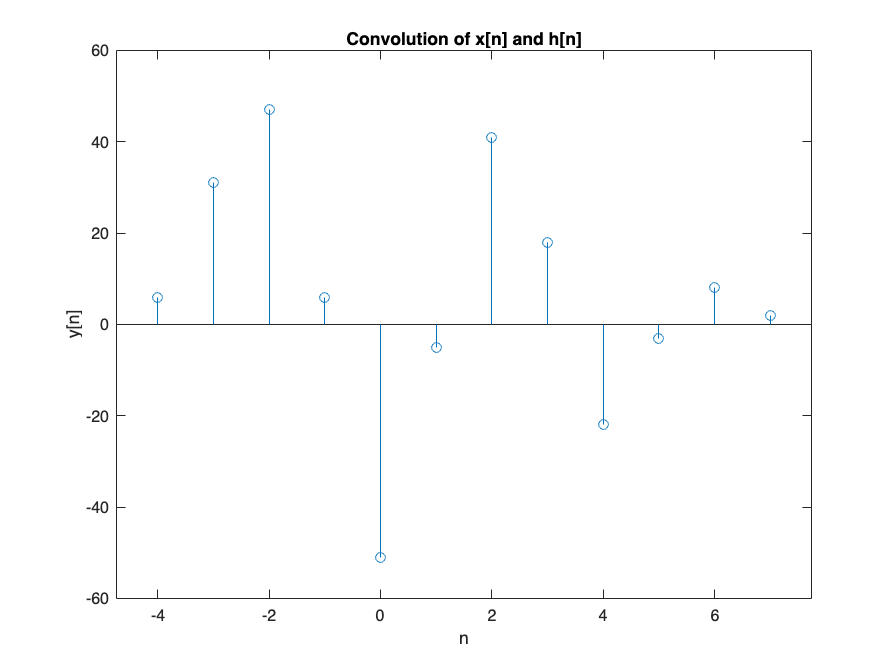


% Plot the result using stem
stem(ny, y);
xlabel('n');
ylabel('y[n]');
title('Convolution of x[n] and h[n]');